# 前日までの勝率から試合結果を予測する(2018-2019シーズンのみ)

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む(prog_NBADataConcatenation.mlxを実行しておく)

load('../data/NBAResults.mat');

2018-19シーズンのチームと試合を抽出する．

seasonStartYearVal=2018;
ind = tbl_teams.SeasonStartYear==seasonStartYearVal;
tbl_teams_tmp=tbl_teams(ind,:);

必要な列をあらかじめ追加しておく

WinRatio=zeros(size(tbl_teams_tmp,1),1);
ScoreRatio=zeros(size(tbl_teams_tmp,1),1);
RankByWins=zeros(size(tbl_teams_tmp,1),1);
tbl_teams_tmp=addvars(tbl_teams_tmp, WinRatio, ScoreRatio, RankByWins);
numTeams=size(unique(tbl_teams_tmp.TeamName),1);

予測対象の開始日を求める

ind = tbl_results.SeasonStartYear==seasonStartYearVal;
seasonStartDate=min(tbl_results.Date(ind))

seasonStartDate = datetime
   2018/10/16


predictionStartDate=seasonStartDate+days(31)

predictionStartDate = datetime
   2018/11/16


テスト用(test)の試合結果の表を作る

ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
    & tbl_results.Date>=predictionStartDate;
tbl_results_test=tbl_results(ind,:);

予測対象の日付一覧を作る

predictionDates=unique(tbl_results_test.Date);
PredictionByWin=[]; %予測結果
ActualWin=[];   %実際の結果

予測対象日ごとに対象試合を選び，予測する

for predictionDate=predictionDates'

予測対象日の試合のみを含む表を抽出する

    tbl_results_test_tmp=tbl_results_test(tbl_results_test.Date==predictionDate,:);

同一シーズンかつ予測対象以前の試合結果を抽出する

    ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
        & tbl_results.Date<predictionDate;
    tbl_results_train=tbl_results(ind,:);

勝，負試合数，および得失点を集計する

集計用の変数を準備する

    Wins=zeros(size(tbl_teams_tmp,1),1);
    Loses=zeros(size(tbl_teams_tmp,1),1);
    ScoresFor=zeros(size(tbl_teams_tmp,1),1);
    ScoresAgainst=zeros(size(tbl_teams_tmp,1),1);

    for n1=1:size(tbl_results_train,1)

それぞれの試合で両チームが何番に対応するかを見つける

        TeamANum=find(tbl_teams_tmp.TeamName==tbl_results_train.Home(n1));
        TeamBNum=find(tbl_teams_tmp.TeamName==tbl_results_train.Away(n1));

各チームの得失点を加える

        ScoresFor(TeamANum)=ScoresFor(TeamANum)+tbl_results_train.HomeScore(n1);
        ScoresFor(TeamBNum)=ScoresFor(TeamBNum)+tbl_results_train.AwayScore(n1);
        ScoresAgainst(TeamANum)=ScoresAgainst(TeamANum)+tbl_results_train.AwayScore(n1);
        ScoresAgainst(TeamBNum)=ScoresAgainst(TeamBNum)+tbl_results_train.HomeScore(n1);

得点の大小で場合分けし，勝・引分・負それぞれに加える

        if tbl_results_train.HomeScore(n1)>tbl_results_train.AwayScore(n1)
            Wins(TeamANum)=Wins(TeamANum)+1;
            Loses(TeamBNum)=Loses(TeamBNum)+1;
        elseif tbl_results_train.HomeScore(n1)<tbl_results_train.AwayScore(n1)
            Loses(TeamANum)=Loses(TeamANum)+1;
            Wins(TeamBNum)=Wins(TeamBNum)+1;
        end
    end

勝率，得点割合を更新する

    WinRatio=Wins./(Wins+Loses);
    ScoreRatio=ScoresFor./(ScoresFor+ScoresAgainst);
    tbl_teams_tmp.WinRatio=WinRatio;
    tbl_teams_tmp.ScoreRatio=ScoreRatio;

勝率→得失点割合の優先順でソートし，その順位を更新する．

    tbl_teams_tmp=sortrows(tbl_teams_tmp,{'WinRatio','ScoreRatio'},'descend');
    RankByWins=(1:size(tbl_teams_tmp,1))';
    tbl_teams_tmp.RankByWins=RankByWins;

予測対象1試合ずつに対し，実際の勝敗と予測勝敗を記録する

    for n1=1:size(tbl_results_test_tmp,1)
        if tbl_results_test_tmp.HomeScore(n1)>tbl_results_test_tmp.AwayScore(n1)
            ActualWin=[ActualWin;1];    %ホーム勝利を1と定義する
        else
            ActualWin=[ActualWin;0];
        end

        TeamANum=find(tbl_teams_tmp.TeamName== tbl_results_test_tmp.Home(n1));
        TeamBNum=find(tbl_teams_tmp.TeamName== tbl_results_test_tmp.Away(n1));
        TeamARank=tbl_teams_tmp.RankByWins(TeamANum);
        TeamBRank=tbl_teams_tmp.RankByWins(TeamBNum);
        if TeamARank<TeamBRank
            PredictionByWin=[PredictionByWin;1];
        else
            PredictionByWin=[PredictionByWin;0];
        end
    end
end

予測正解を判定する．

isPredictionCorrect= ActualWin==PredictionByWin;

予測正解率を算出する

predictionAccuracy=mean(isPredictionCorrect)

predictionAccuracy = 0.6454

結果と予測，予測正解かどうかを図示する

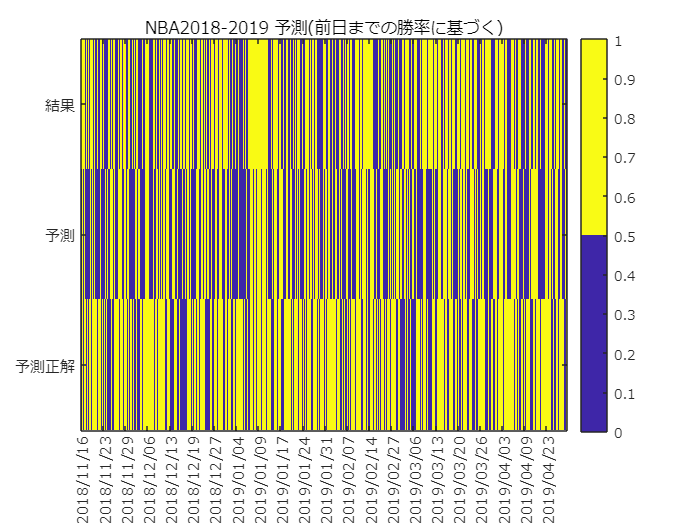

figure
imagesc([ActualWin PredictionByWin isPredictionCorrect]');
cmap=colormap(gca);
colormap(cmap([1,end],:));
colorbar;
set(gca,'fontname','メイリオ');
xticks(1:50:size(tbl_results_test,1));
xticklabels(string(tbl_results_test.Date(1:50:end)));
yticks(1:3);
yticklabels({'結果','予測','予測正解'});
title('NBA2018-2019 予測(前日までの勝率に基づく)');
exportgraphics(gcf,'fig_NBA20182019PredictionByDate01.pdf');

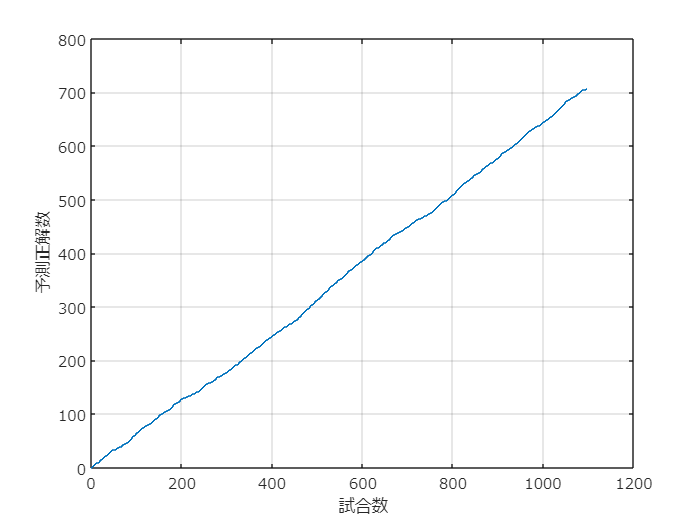

figure
stairs(cumsum(isPredictionCorrect));
grid on;
set(gca,'fontname','メイリオ');
xlabel('試合数');ylabel('予測正解数');
exportgraphics(gcf,'fig_NBA20182019CorrectPredictionsByDate01.pdf');